# OS dispersion model for olfactory interface in MR system

## **Function: GaussDispersion_ppm**

    GaussDispersion_ppm returns matrix the average concentration of diffusion substance at position (x,y,z) for an odor generator at height H with source strength Q g/sec for odor chemicals with molecular weight mole g/mol. U represent a wind in x direction while y stands for the crosswind axis. 

### Syntax

    conc =  GaussDispersion_ppm(x,y,z,U,H,Q,mol)

### Description

    conc =  GaussDispersion_ppm(x,y,z,U,H,Q,mol) returns matrix conc values as double

## **Function: plot_contourMatrix**

    plot_contourMatrix plot contour matrix M in 3D space to a given axis ax

### Syntax

    plot_contourMatrix(ax,M,z_,x_,y_,theta,cmap_max,cmap_min,cmap,verticle)

### Description

    plot contour matrix M in 3D space to with center at x_,y_,z_ and orientation angle theta in x-y plane with color option cmap_max,cmap_min,cmap.

## Function: OG_Demand_Check

    OG_Demand_Check compares the orientation of user's head, position, and velocity with the estimated 5-ppm boundaries of odor emmisions at the height of user's nose.

### Syntax

    demand_check = OG_Demand_Check(user_track,OG_pos,range_,OG_dt)

### Description

    demand_check returns the index of

## Example

Given wind speed 0.92 m/s, 10 OG emits Q=4.2e-6 g/sec of OS2 (gardenia, mol=156.24 g/mol)  at height H=1.6 m, plots controur with average concentration level of 30, 20 10 5 ppm.

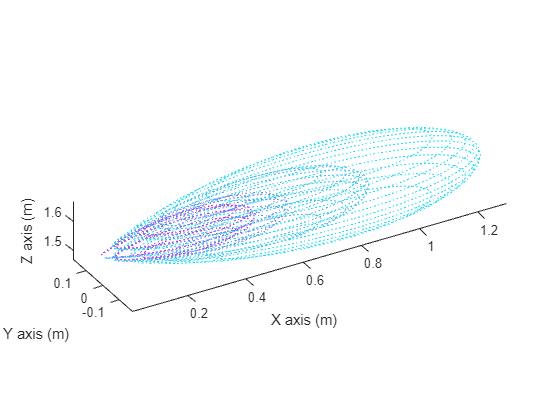

load colormap_OG.mat
Q=4.2e-6;
U=0.92;
H=1.6; %0 for ground level
[x,y]=meshgrid(0:0.01:2.5,-1:0.01:1);
z_list = 1.5:0.02:1.7;
thred=[30,20,10,5];
figure(1)
xlabel('X axis (m)');
ylabel('Y axis (m)');
zlabel('Z axis (m)');
hold on
ax=gca;
cmap_max=40;cmap_min=0;
for i = 1: length(z_list)
    z = z_list(i);
    conc=GaussDispersion_ppm(x,y,z,U,H,Q,156.24);
    M = contourc(0:0.01:2.5,-1:0.01:1,conc,thred);
    plot_contourMatrix(ax,M,z-0.03,0,0,0,cmap_max,cmap_min,cmap);
end

Given zero wind speed, OG emits Q=1.2e-7 g/sec of OS3 (osmanthyus, mol=150.18 g/mol)  at height H=0 m, plots controur with average concentration level of 30, 20 10 5 ppm.

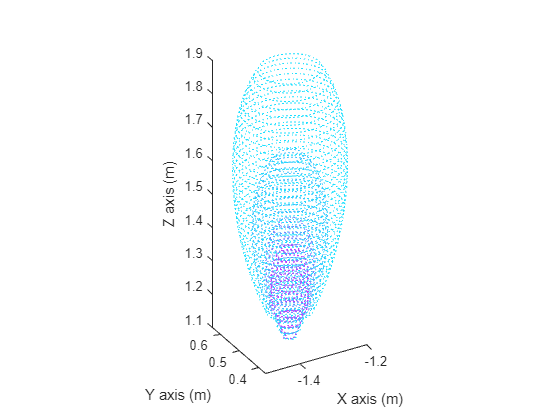

Q=2.4e-7; 
H=0; %0 for ground level
x_list = 0.03:0.02:0.83;
[y,z]=meshgrid(-1:0.01:1.5,-0.5:0.01:0.5);
thred=[30,20,10,5];
figure(2)
xlabel('X axis (m)');
ylabel('Y axis (m)');
zlabel('Z axis (m)');
hold on
ax=gca;
OG_pos=[-1.35 0.5 1.07];
for i = 1: length(x_list)
    x = x_list(i);
    U=(0.77/1000/x)^(1/3); %calculate convection air speed with heat power of 0.77W of each OG
    conc=GaussDispersion_ppm(x,y,z,U,H,Q,150.18);
    M = contourc(-1:0.01:1.5,-0.5:0.01:0.5,conc,thred);
    plot_contourMatrix(ax,M,x+OG_pos(3),OG_pos(1),OG_pos(2),0,cmap_max,cmap_min,cmap)   
end

Extracting the estimated 5-ppm boundaries of odor emmisions at the height of user's nose (i.e. Height=1.56 m) which is compared with the user's  head vector, position, and velocity with considering both the harware response time hw_dt=0.07 sec and odor emmision time from OG the user's nose. Load an example of human user tracking from MR system from example.mat as test including human head vector, position, and velocity.

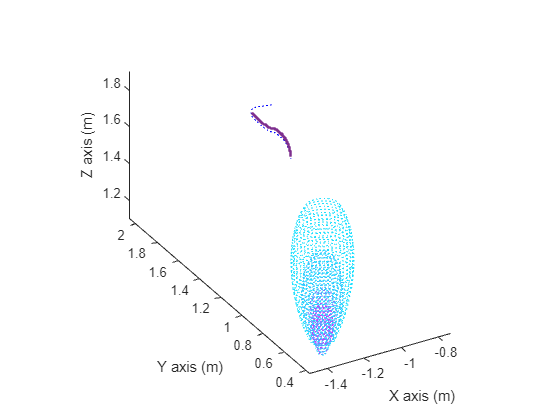

load example.mat
Q=2.4e-7;
H=0;
Height=1.56;
[y,z]=meshgrid(-1:0.01:1.5,-0.5:0.01:0.5);
OG_pos=[-1.35 0.5 1.07]; % OG3 position
OG_time_2_nose = 4.8;
x=Height-OG_pos(3);
conc=GaussDispersion_ppm(x,y,z,U,H,Q,150.18);
M = contourc(-1:0.01:1.5,-0.5:0.01:0.5,conc,thred);
N = M(2,1);index = N+1;X_ = M(1,2:index);Y_ = M(2,2:index);
X=X_*cos(-pi)-Y_*sin(-pi);Y=X_*sin(-pi)+Y_*cos(-pi);
range_ = [X;Y]; % emission distribution estimation at Height
load example.mat % human user exploration data dtream with position,head vector, and velocity
hw_dt = 0.07; 
OG_dt = hw_dt+OG_time_2_nose;
demand_check = OG_Demand_Check(test,OG_pos,range_,OG_dt);
figure(2)
hold on
plot3(H_x,H_y,H_z,'b:')
plot3(H_x(demand_check),H_y(demand_check),H_z(demand_check)+0.02,'.','Color',[0.4940 0.1840 0.5560],'MarkerSize',6)